%%导线直径为D
D=0.0096;
%%一般风速为v
v=0.6;
ta=linspace(20,21.5,100);
tc=20;
%%导体表面空气膜的热传导率为lambda
lambda=2.42*10^(-2)+7*10^(-5).*(0.5*(ta)+0.5*(tc));
%%导体表面空气膜动态粘度vf
vf=1.32*10^(-5)+9.6*10^(-8).*(0.5*(ta)+0.5*(tc));
%%雷诺数为Re
Re=1.644*10^(9)*v*D.*(0.5*(tc)+0.5*(ta)).^(-1.78)

Re = 	1.0e+04 *

   4.576051509238954   4.572967764893963   4.569887264887991   4.566810004581691   4.563735979344102   4.560665184552634   4.557597615593042   4.554533267859415   4.551472136754155   4.548414217687959   4.545359506079801   4.542307997356910   4.539259686954762   4.536214570317053   4.533172642895683   4.530133900150739   4.527098337550477   4.524065950571310   4.521036734697776   4.518010685422536   4.514987798246348   4.511968068678049   4.508951492234537   4.505938064440763   4.502927780829700   4.499920636942337   4.496916628327652   4.493915750542603   4.490917999152104   4.487923369729012   4.484931857854109   4.481943459116085   4.478958169111519   4.475975983444864   4.472996897728429   4.470020907582361   4.467048008634634   4.464078196521019   4.461111466885086   4.458147815378169   4.455187237659360   4.452229729395490   4.449275286261109   4.446323903938475   4.443375578117534   4.440430304495901   4.437488078778850   4.434548896679293   4.431612753917763   

%%最终的对流散热功率为Qc
Qc=0.57.*lambda.*(Re.^(0.71)).*pi.*(abs(tc-ta))

Qc = 	1.0e+02 *

                   0   0.014140684540430   0.028268426926044   0.042383243696301   0.056485151363496   0.070574166412807   0.084650305302370   0.098713584463308   0.112764020299799   0.126801629189131   0.140826427481751   0.154838431501323   0.168837657544778   0.182824121882367   0.196797840757727   0.210758830387915   0.224707106963473   0.238642686648479   0.252565585580600   0.266475819871145   0.280373405605118   0.294258358841264   0.308130695612141   0.321990431924147   0.335837583757588   0.349672167066726   0.363494197779833   0.377303691799239   0.391100665001388   0.404885133236882   0.418657112330551   0.432416618081479   0.446163666263073   0.459898272623109   0.473620452883781   0.487330222741757   0.501027597868224   0.514712593908943   0.528385226484295   0.542045511189343   0.555693463593864   0.569329099242414   0.582952433654371   0.596563482323987   0.610162260720441   0.623748784287881   0.637323068445478   0.650885128587484   0.664434980083265   



%%导线表面的辐射系数为epsilon
epsilon=0.9;
%%导线直径为D
D=0.0096;
%%斯蒂芬-包尔兹曼常数为sigma
sigma=0.0000000567

sigma =      5.670000000000000e-08


%%最终的辐射散热功率为Qr
Qr=pi.*epsilon.*D.*sigma.*abs((tc+273).^4-(ta+273).^4)

Qr =                    0   0.002346385023128   0.004693134062032   0.007040247154366   0.009387724337764   0.011735565649881   0.014083771128373   0.016432340810901   0.018781274735107   0.021130572938655   0.023480235459207   0.025830262334434   0.028180653601982   0.030531409299526   0.032882529464736   0.035234014135288   0.037585863348839   0.039938077143071   0.042290655555659   0.044643598624291   0.046996906386629   0.049350578880363   0.051704616143176   0.054059018212765   0.056413785126797   0.058768916922973   0.061124413638982   0.063480275312530   0.065836501981290   0.068193093682971   0.070550050455272   0.072907372335903   0.075265059362550   0.077623111572927   0.079981529004739   0.082340311695698   0.084699459683522   0.087058973005906   0.089418851700575   0.091779095805245   0.094139705357644   0.096500680395474   0.098862020956468   0.101223727078351   0.103585798798856   0.105948236155697   0.108311039186609   0.110674207929328   0.113037742421595   0.1154016427




%%导线表面的吸热系数为alpha
alpha=(0.23+0.46)/2

alpha =    0.345000000000000


%%直射点纬度为delta
delta=23.45.*sin(2.*pi.*(284+182)./365)

delta =   23.120484116651820


%%当地维度为altitude
latitude=46.089

latitude =   46.088999999999999


SolarAltitude=90-abs(latitude-delta)

SolarAltitude =   67.031484116651825


%%当前导线所处环境日照辐射强度为q
q=1098.*cos(SolarAltitude).*exp(-0.057./cos(SolarAltitude))

q =     -6.050263196996642e+02


Qs=alpha.*D.*q

Qs =   -2.003847170845288



%%集肤效应系数为k
k=0.0025

k =    0.002500000000000


%%20℃下导线材料温度系数为alpha20
alpha20=0.00403

alpha20 =    0.004030000000000


%%20℃下导线的电阻为R20
R20=0.0000000265./((0.0096./2).^2.*pi)

R20 =      3.661116312443774e-04


%%tc温度下导线的直流电阻为Rd
Rd=R20.*(1+alpha20.*(tc-20))

Rd =      3.661116312443774e-04


%%tc温度下导线的交流电阻为Rd
Rc=(1+k).*Rd

Rc =      3.670269103224883e-04


subplot(2,1)
I=((Qc+Qr-Qs)./Rc).^(1./2)

I = 	1.0e+02 *

   0.738896048420886   0.965340960948079   1.147800700976327   1.304859247523819   1.444824294109051   1.572267678649031   1.690024657129718   1.799997431577530   1.903535745979075   2.001638462743654   2.095069401505257   2.184428201097638   2.270195869402411   2.352765266560982   2.432462199210170   2.509560435706444   2.584292655699638   2.656858603788008   2.727431273344468   2.796161672751877   2.863182552131706   2.928611354952751   2.992552582926406   3.055099710748456   3.116336751199174   3.176339545618019   3.235176836457845   3.292911165283487   3.349599629735149   3.405294525624492   3.460043894779430   3.513891995017797   3.566879705368438   3.619044877123129   3.670422639317233   3.721045665669020   3.770944408760640   3.820147306245311   3.868680963060566   3.916570312975070   3.963838762264217   4.010508317873913   4.056599702072026   4.102132455289489   4.147125028605269   4.191594867122351   4.235558485308198   4.279031535226776   4.322028868465208   4

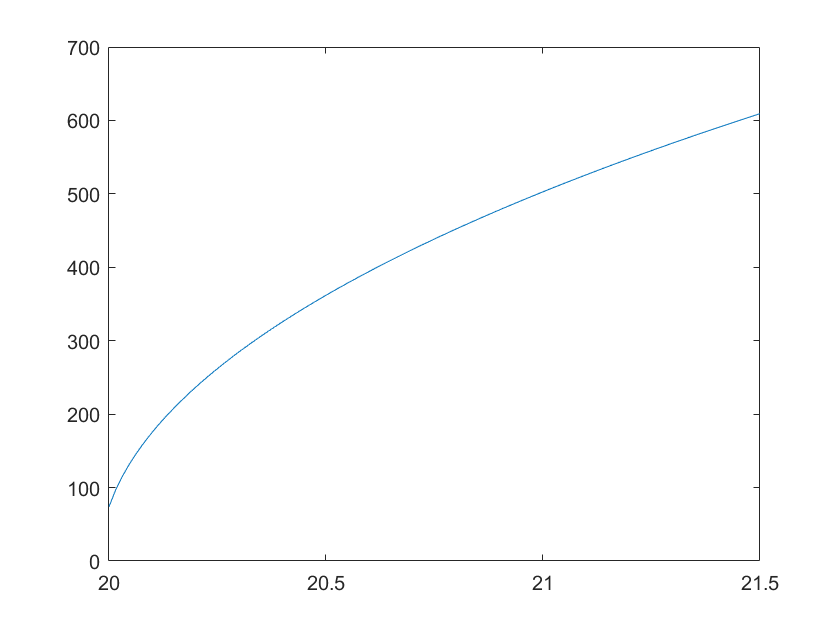

plot(ta,I)